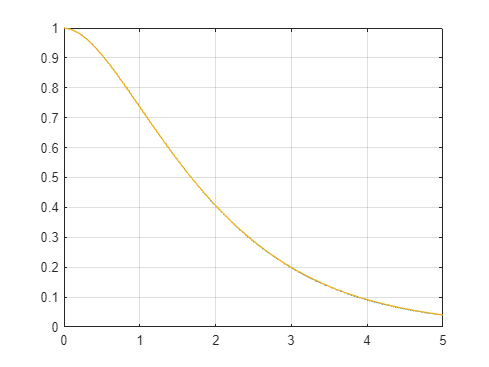

addpath(genpath('./'));

% test
Y0 = 1;       
X = linspace(0, 5, 51); 

[T1, Y1] = ode23(@f31a, X, Y0); % розв'язання системи 
[T2, Y2] = ode45(@f31a, X, Y0); 

u = @(x)(exp(-x).*(1+x)); 
plot(T1, Y1, T2, Y2, X, u(X)), grid on;

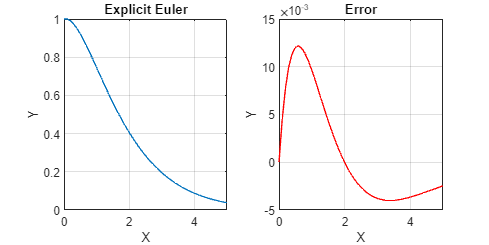


[X, Y] = eulerSolver(@f31a, 0, Y0, 5, 51, SideEnum.Left);
complexPlotWithError(X, Y, u, "Explicit Euler");

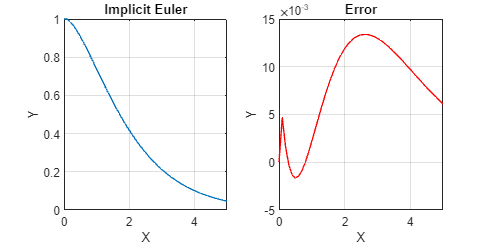

% complexPlot(X, Y, "Explicit Euler");

[X, Y] = eulerSolver(@f31a, 0, Y0, 5, 51, SideEnum.Right);
complexPlotWithError(X, Y, u, "Implicit Euler");

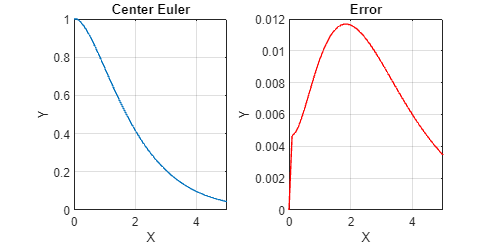

%complexPlot(X, Y, "Implicit Euler");

[X, Y] = eulerSolver(@f31a, 0, Y0, 5, 51, SideEnum.Center);
complexPlotWithError(X, Y, u, "Center Euler");

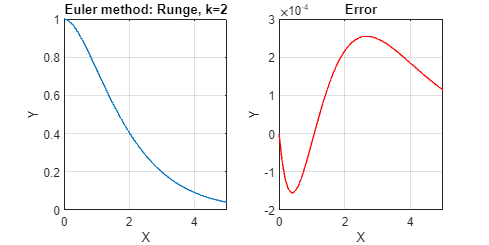

%complexPlot(X, Y, "Center Euler");

[X, Y] = runge2EulerSolver(@f31a, 0, Y0, 5, 51);
complexPlotWithError(X, Y, u, "Euler method: Runge, k=2");

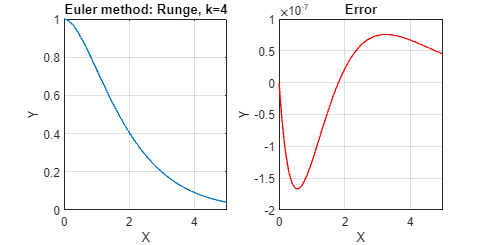

%complexPlot(X, Y, "Euler method: Runge, k=2");

[X, Y] = runge4EulerSolver(@f31a, 0, Y0, 5, 51);
complexPlotWithError(X, Y, u, "Euler method: Runge, k=4");

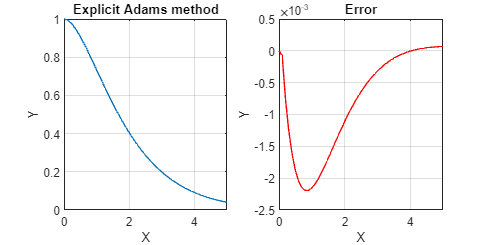

%complexPlot(X, Y, "Euler method: Runge, k=4");

[X, Y] = adamsSolver(@f31a, 0, Y0, 5, 51, SideEnum.Left);
complexPlotWithError(X, Y, u, "Explicit Adams method");

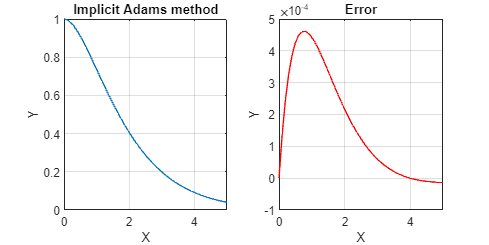

%complexPlot(X, Y, "Explicit Adams method");

[X, Y] = adamsSolver(@f31a, 0, Y0, 5, ...
    51, SideEnum.Right);
complexPlotWithError(X, Y, u, "Implicit Adams method");

%complexPlot(X, Y, "Implicit Adams method");

function F = f31a(t, U)   
    % підфункція правої частини системи 
    F = exp(-t) - U;
end